# Fitting using Polynomials

In MATLAB a polynomial $f(x)$ is defined using its coefficients $c(i)$ definiert. Meaning the vector $C=[c(1), c(2),...c(n), c(n+1)]$ represents the polynomial:


$$p(x)=c_1x^n+c_2x^{n-1}+c_3x^{n-2}+ ... + c_{n-1}x^2+c_{n}x+c_{n+1}$$


For example $p(x)=3x^2-2x-4$  would be saved as the following vector.

p = [3 -2 -4];

In order to evaluate a polynomial, one can use the function  polyval(c,x). This function returns the values of the polynomial $c$ for the given positions $x$.

For example lets evaluate p at the positions 1 to 5.

polyval(p,1:5)

ans =     -3     4    17    36    61


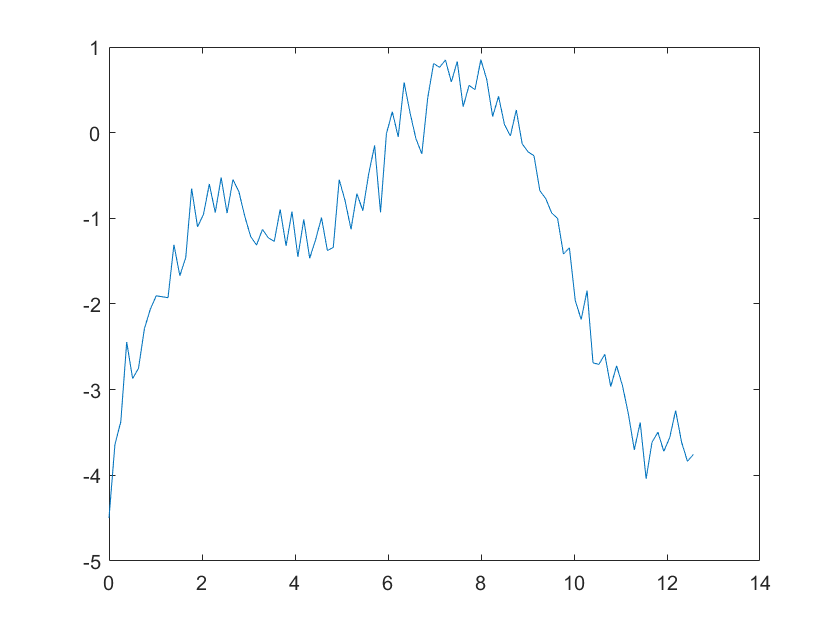

load('PolynomialExample.mat')
plot(x,y)

Lets determine the two maximas in the present data.

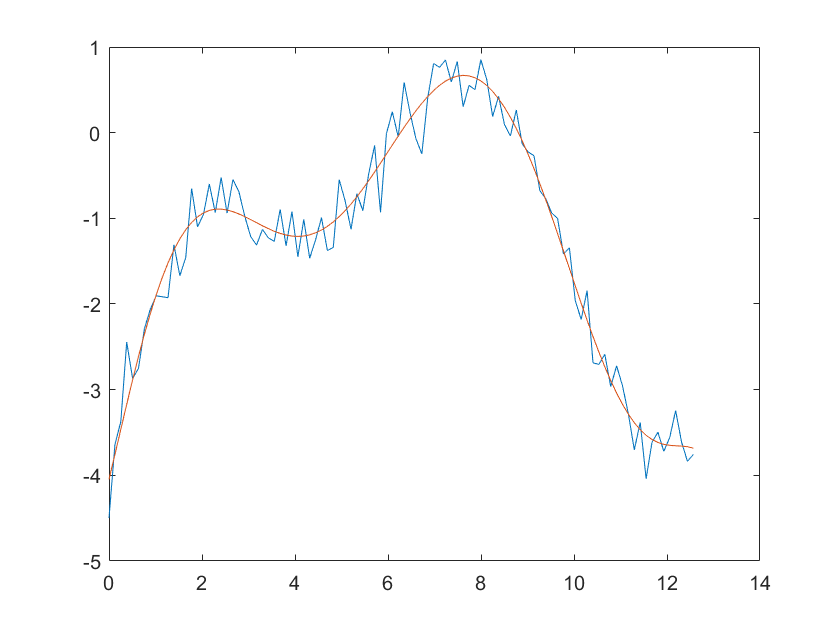

deg=7;
c=polyfit(x,y,deg);
yFit = polyval(c,x);
plot(x,y)
hold on
plot(x,yFit);
hold off

The function polyfit returns the fitting polynomial in form of the previously discussed vector. Using "polyder", we get the coefficients of the differentiated polynomial. The local maxima extrema can now be determined by calculating the roots with the built in function.

rts=roots(polyder(c))

rts =   12.2376 + 0.1356i
  12.2376 - 0.1356i
   7.6278 + 0.0000i
   4.0581 + 0.0000i
   2.3572 + 0.0000i
  -0.7371 + 0.0000i


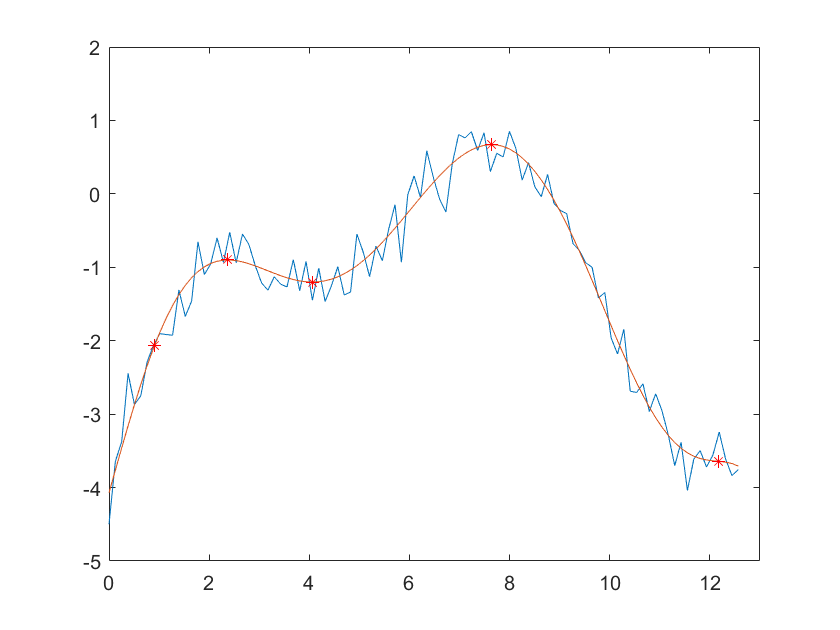

hold on
plot(abs(rts),polyval(c,abs(rts)),'*r') % should define the ranges here and use abs(rts)
xlim([0, 13])
ylim([-5 2])
hold off

Sind die Nullstellen eines Polynoms bekannt so kann MATLAB daraus auch direkt die Koeffizienten bestimmen.

poly(rts)

ans = 	1.0e+05 *

    0.0000    0.0001   -0.0117    0.2003   -1.3154    3.2350   -0.7033   -4.4582
